## Post Process Simulation Data:

%Drag Mode
L1= -0.58;
sim walkingMechanism_model_v2.slx;

xyz= ans.xyz;
t= ans.tout;
tran_angles= ans.trans_angles;
horz_stride= abs(max(xyz(:,1)) - min(xyz(:,1)));
vert_stride= abs(max(xyz(:,2)) - min(xyz(:,2)));
force= ans.Force;
torque= ans.torqe;
max_torque= max(abs(max(torque)), abs(min(torque)));
max_force= max(abs(max(force)), abs(min(force)));



%Obstacle Avoidance Mode
L1= 1.80;
sim walkingMechanism_model_v2.slx;

xyz_obs= ans.xyz;
t_obs= ans.tout;
tran_angles_obs= ans.trans_angles;
horz_stride_obs= abs(max(xyz_obs(:,1)) - min(xyz_obs(:,1)));
vert_stride_obs= abs(max(xyz_obs(:,2)) - min(xyz_obs(:,2)));
force_obs= ans.Force;
torque_obs= ans.torqe;
max_torque_obs= max(abs(max(torque_obs)), abs(min(torque_obs)));
max_force_obs= max(abs(max(force_obs)), abs(min(force_obs)));


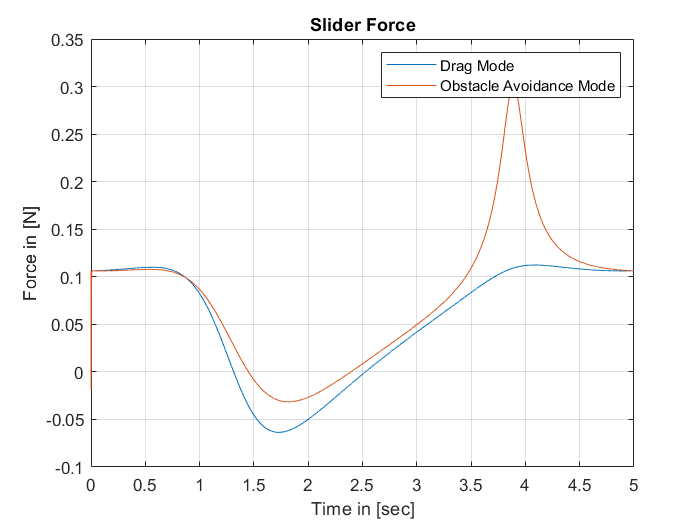




figure(1);
plot(t,force, t, force_obs);
grid on;xlabel('Time in [sec]');ylabel('Force in [N]');title('Slider Force');legend('Drag Mode', 'Obstacle Avoidance Mode');

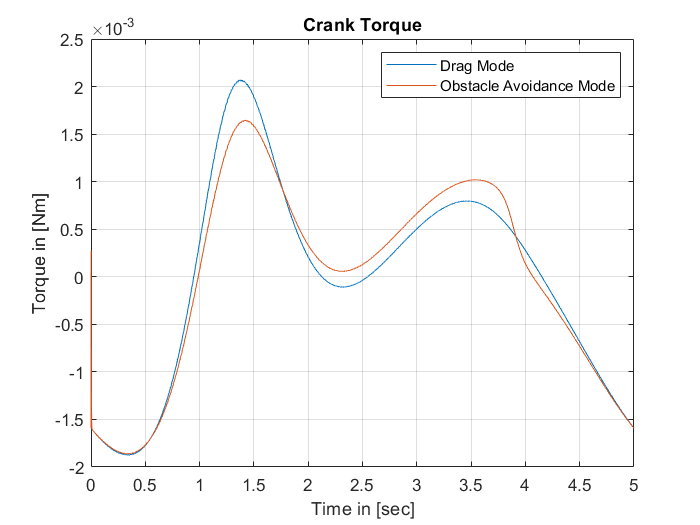


figure(2);
plot(t,torque,t,torque_obs);
grid on;xlabel('Time in [sec]');ylabel('Torque in [Nm]');title('Crank Torque');legend('Drag Mode', 'Obstacle Avoidance Mode');

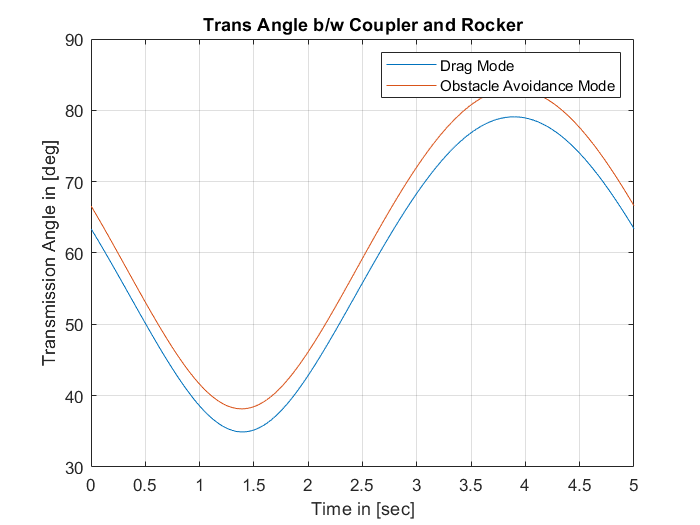

figure(3);
plot(t,tran_angles,t, tran_angles_obs);
grid on;xlabel('Time in [sec]');ylabel('Transmission Angle in [deg]');title('Trans Angle b/w Coupler and Rocker');legend('Drag Mode', 'Obstacle Avoidance Mode');

max_tran_angle= max(tran_angles)

max_tran_angle = 79.0881

min_tran_angle= min(tran_angles)

min_tran_angle = 34.9159

trans_range= max_tran_angle-min_tran_angle

trans_range = 44.1722

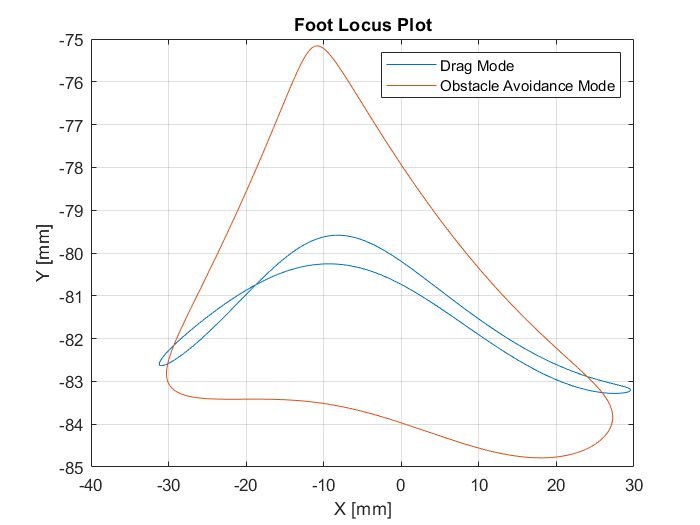


figure(4);
plot(xyz(:,1),xyz(:,2), xyz_obs(:,1),xyz_obs(:,2));
grid on;xlabel('X [mm]');ylabel('Y [mm]');title('Foot Locus Plot');legend('Drag Mode', 'Obstacle Avoidance Mode');